%Group Assignment The selection of variables are within the following range
%y0  = [0.1-10  0.1-10  0.1-10]; %i.e. plant, hare, lynx
%a1 = [1-10];
%a2  = [0.1-1];
%b1 = [1-10];
%b2 = [1-10];
%d1 = [0.1-1];
%d2 = [0.01-1];
%t0 = 0; 


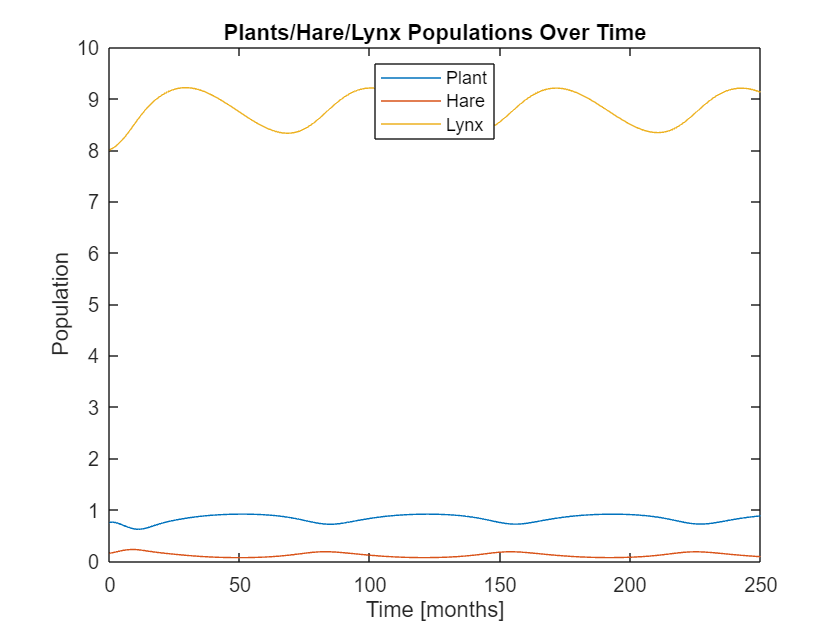

%Scenario 1: The system exhibits stable oscillations with a periodicity of approximately 70 months.
y0  = [0.75  0.15  8]; %i.e. plant, hare, lynx
a1 = [5];
a2  = [0.1];
b1 = [3];
b2 = [1];
d1 = [0.4];
d2 = [0.01];
t0 = 0; 
tfinal=250;
tspan=[t0 tfinal];

[t,y] = ode45(@(t,y) plants_hare_lynx(t,y,a1,a2,b1,b2,d1,d2), tspan, y0);
figure("Name",'Plant-Hare-Lynx')
plot(t,y)
title('Plants/Hare/Lynx Populations Over Time')
xlabel('Time [months]')
ylabel('Population')
legend('Plant','Hare','Lynx','Location','North')

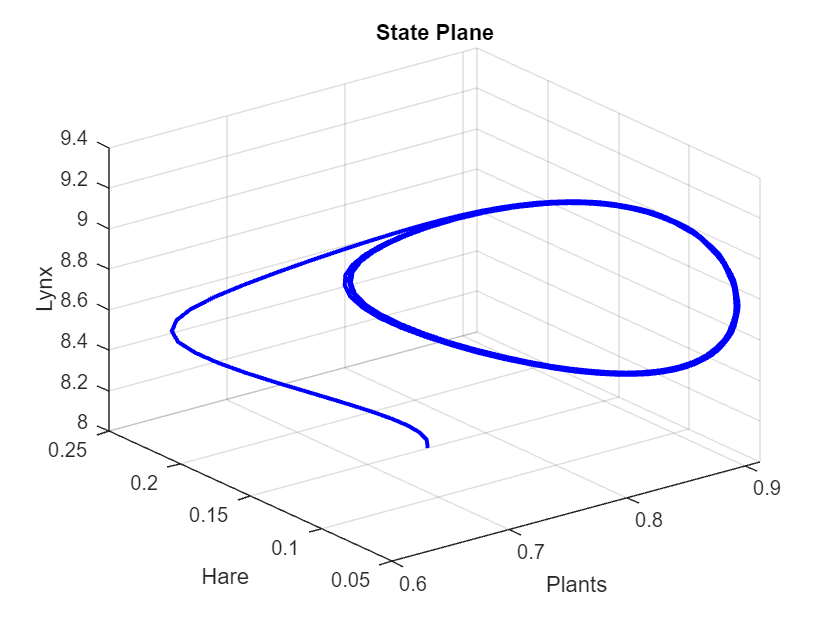


% Plot 3D curve
plot3(y(:,1), y(:,2), y(:,3), 'b', 'LineWidth', 2);
xlabel('Plants');
ylabel('Hare');
zlabel('Lynx');
title('State Plane');
grid on;

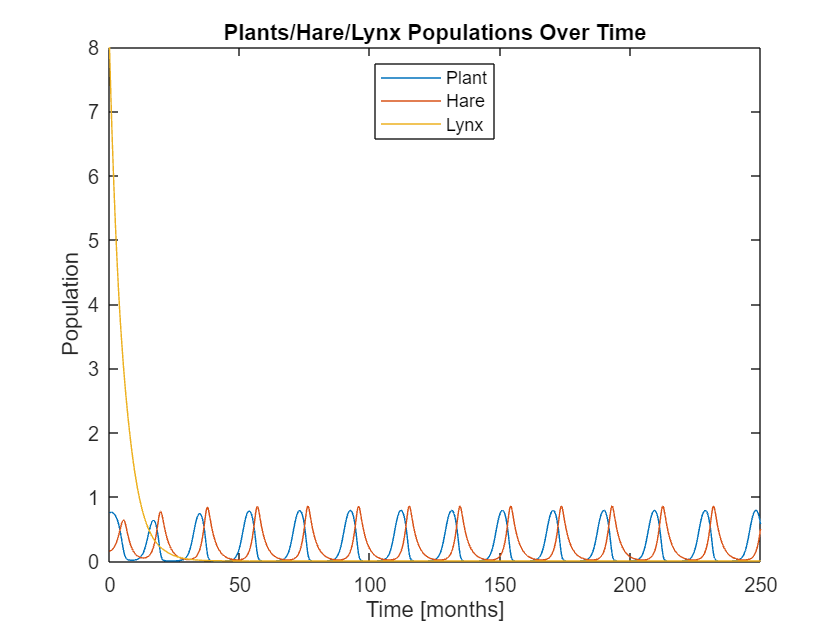

%Scenario 2: The lynx population goes extinct (population very close to zero) after a year, plants and hares stabilize within 120 months.

y0  = [0.75  0.15  8]; %i.e. plant, hare, lynx
a1 = [4.8];
a2  = [0.1]; 
b1 = [3];
b2 = [2];
d1 = [0.4];
d2 = [0.2]; %changed parameter
t0 = 0; 
tfinal=250;
tspan=[t0 tfinal];

[t,y] = ode45(@(t,y) plants_hare_lynx(t,y,a1,a2,b1,b2,d1,d2), tspan, y0);
figure("Name",'Plant-Hare-Lynx')
plot(t,y)
title('Plants/Hare/Lynx Populations Over Time')
xlabel('Time [months]')
ylabel('Population')
legend('Plant','Hare','Lynx','Location','North')

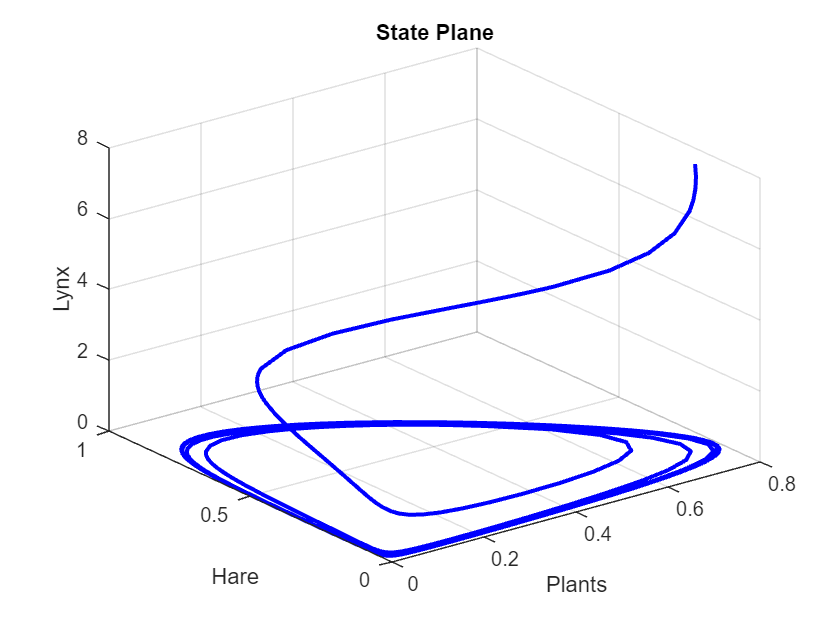


% Plot 3D curve
plot3(y(:,1), y(:,2), y(:,3), 'b', 'LineWidth', 2);
xlabel('Plants');
ylabel('Hare');
zlabel('Lynx');
title('State Plane');
grid on;

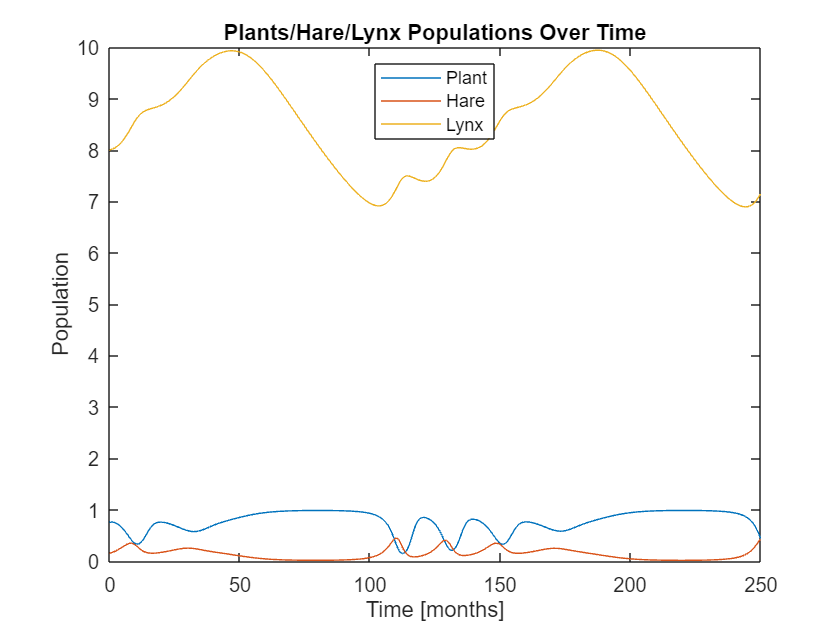


%Scenario 3: The system shows chaotic behavior and the lynx population peaks twice within the 200-months period. What makes this behavior 
% chaotic and not oscillating or random? Hint: Chaotic behavior is deterministic, sensitive to initial conditions, bounded and irregular.
y0  = [0.75  0.15  8]; %i.e. plant, hare, lynx
a1 = [4.8];
a2  = [0.1];
b1 = [3];
b2 = [2];
d1 = [0.4];
d2 = [0.01];
t0 = 0; 
tfinal=250;
tspan=[t0 tfinal];

[t,y] = ode45(@(t,y) plants_hare_lynx(t,y,a1,a2,b1,b2,d1,d2), tspan, y0);
figure("Name",'Plant-Hare-Lynx')
plot(t,y)
title('Plants/Hare/Lynx Populations Over Time')
xlabel('Time [months]')
ylabel('Population')
legend('Plant','Hare','Lynx','Location','North')

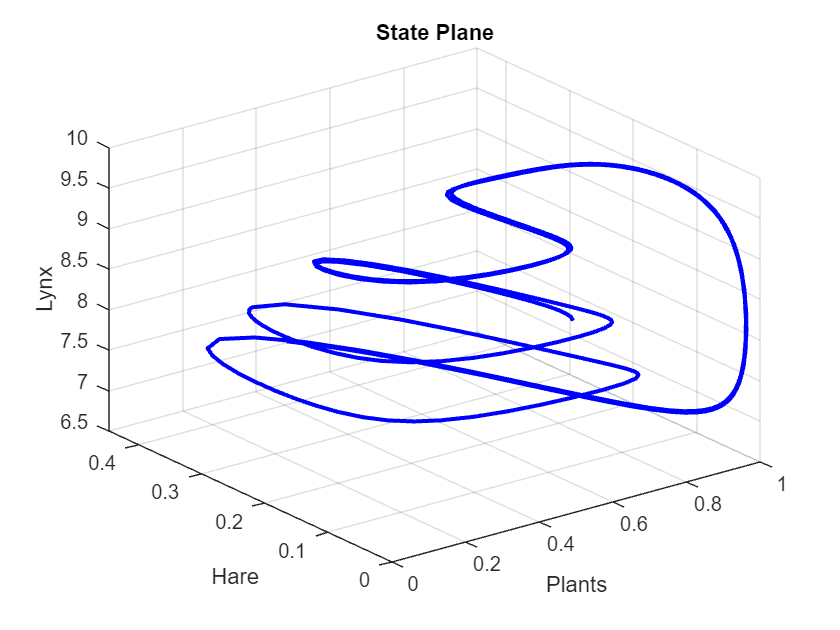


% Plot 3D curve
plot3(y(:,1), y(:,2), y(:,3), 'b', 'LineWidth', 2);
xlabel('Plants');
ylabel('Hare');
zlabel('Lynx');
title('State Plane');
grid on;